# FNN CNN LSTM - Get Data Plot

## Set index of each items of data

i=1;
capacityIdx = i; i=i+1;
cycleTimeHourIdx = i; i=i+1;
restTimeHourIdx = i; i=i+1;
restCycleIdx = i; i=i+1;
cTempMaxIdx = i; i=i+1;
cCcEndTimeSecIdx = i; i=i+1;
dTempMaxIdx = i; i=i+1;
dCcEndTimeSecIdx = i; i=i+1;
ohmIdx = i; i=i+1;
re_cIdx = i; i=i+1;
re_dIdx = i; i=i+1;
cycleNoChageReIdx = i; i=i+1;
cycleNoDischageReIdx = i; i=i+1;
pattern_dVoltIdx = i; i=i+1;
pattern_tempdx = i; i=i+1;
pattern_CC_ampsIdx = i; i=i+1;
charVIT_Index = i; 


load cap_gen_05_org
load cap_gen_06_org
load cap_gen_07_org

[https://medium.com/batterybits/comparison-of-open-datasets-for-lithium-ion-battery-testing-fd0de091ca2](https://medium.com/batterybits/comparison-of-open-datasets-for-lithium-ion-battery-testing-fd0de091ca2)

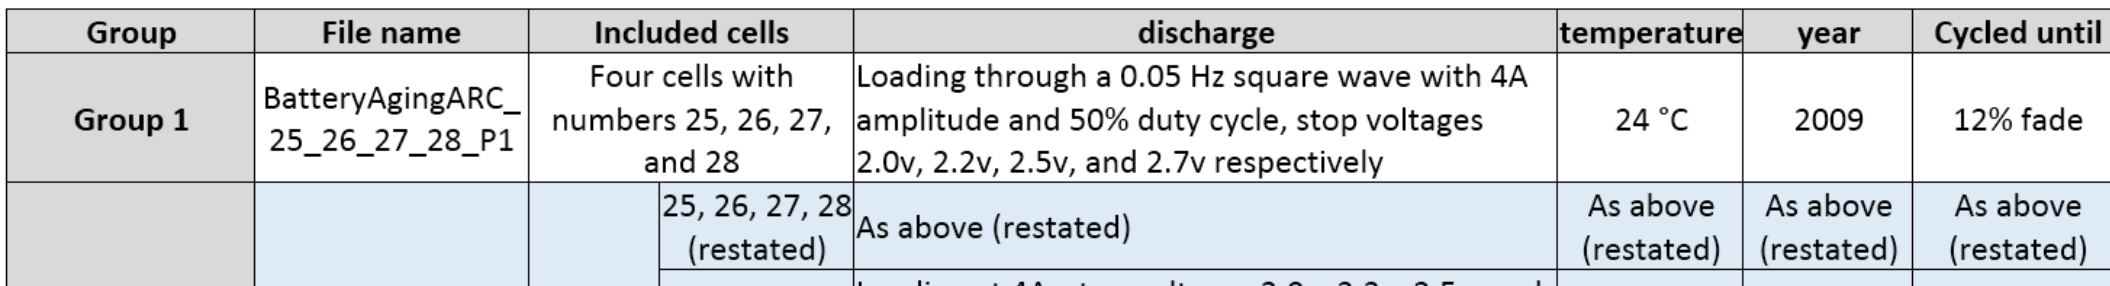

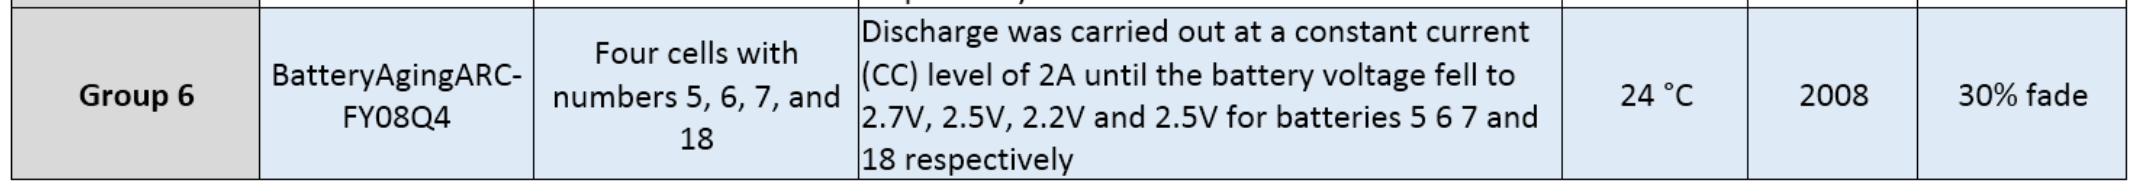

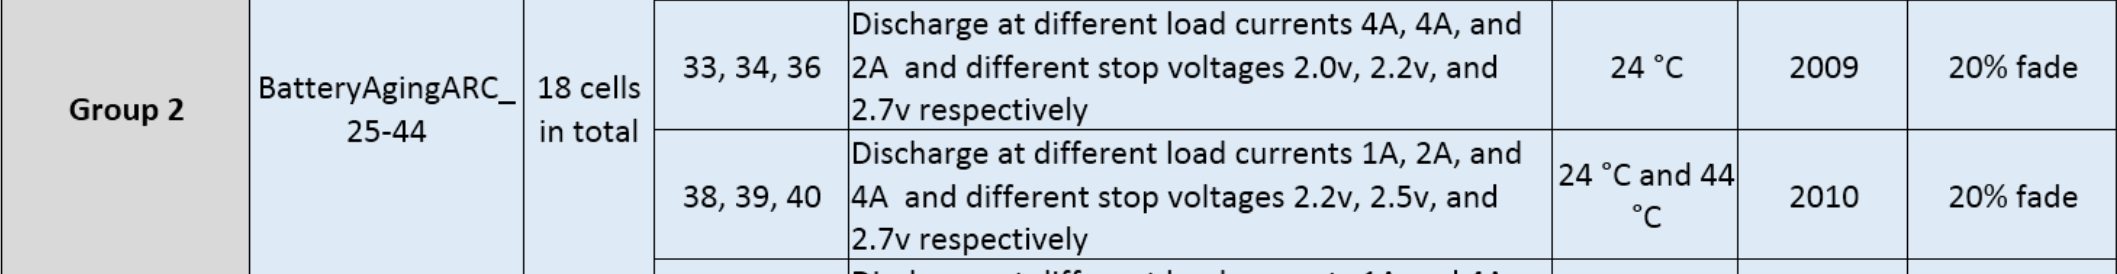

% figure
len = length(cap_gen_05_org) + 5

len = 173

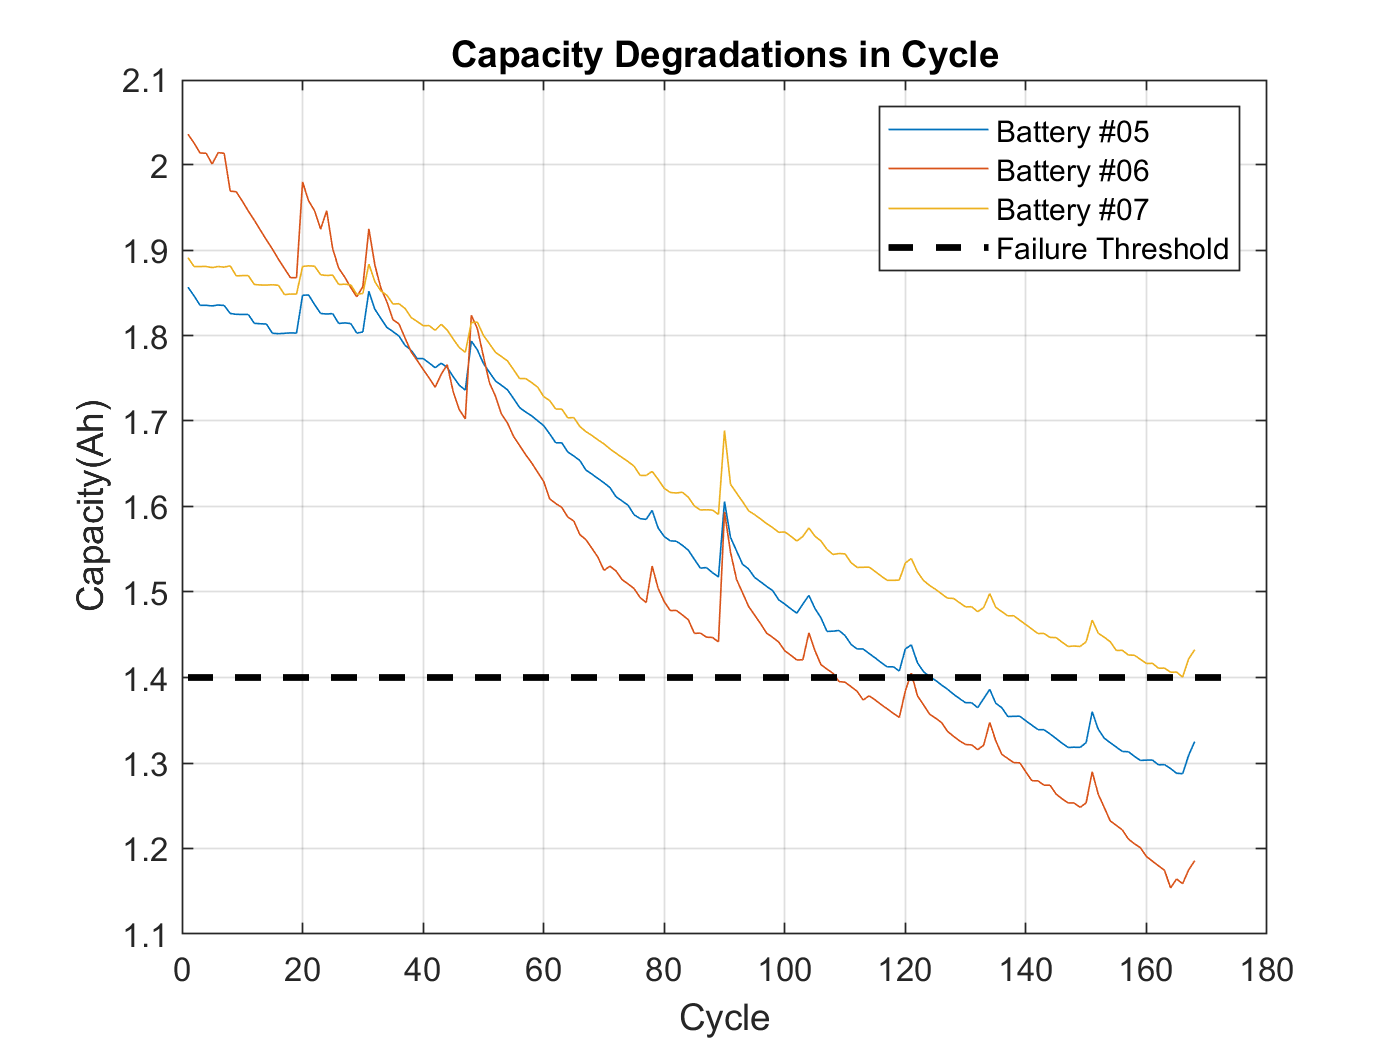

plot(cap_gen_05_org), hold on, plot(cap_gen_06_org), plot(cap_gen_07_org)
plot(1:len, 1.4*ones(1, len),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #05', 'Battery #06', 'Battery #07', 'Failure Threshold')
title('Capacity Degradations in Cycle')

load cap_gen_05
load cap_gen_06
load cap_gen_07


len = length(cap_gen_05) + 5

len = 172

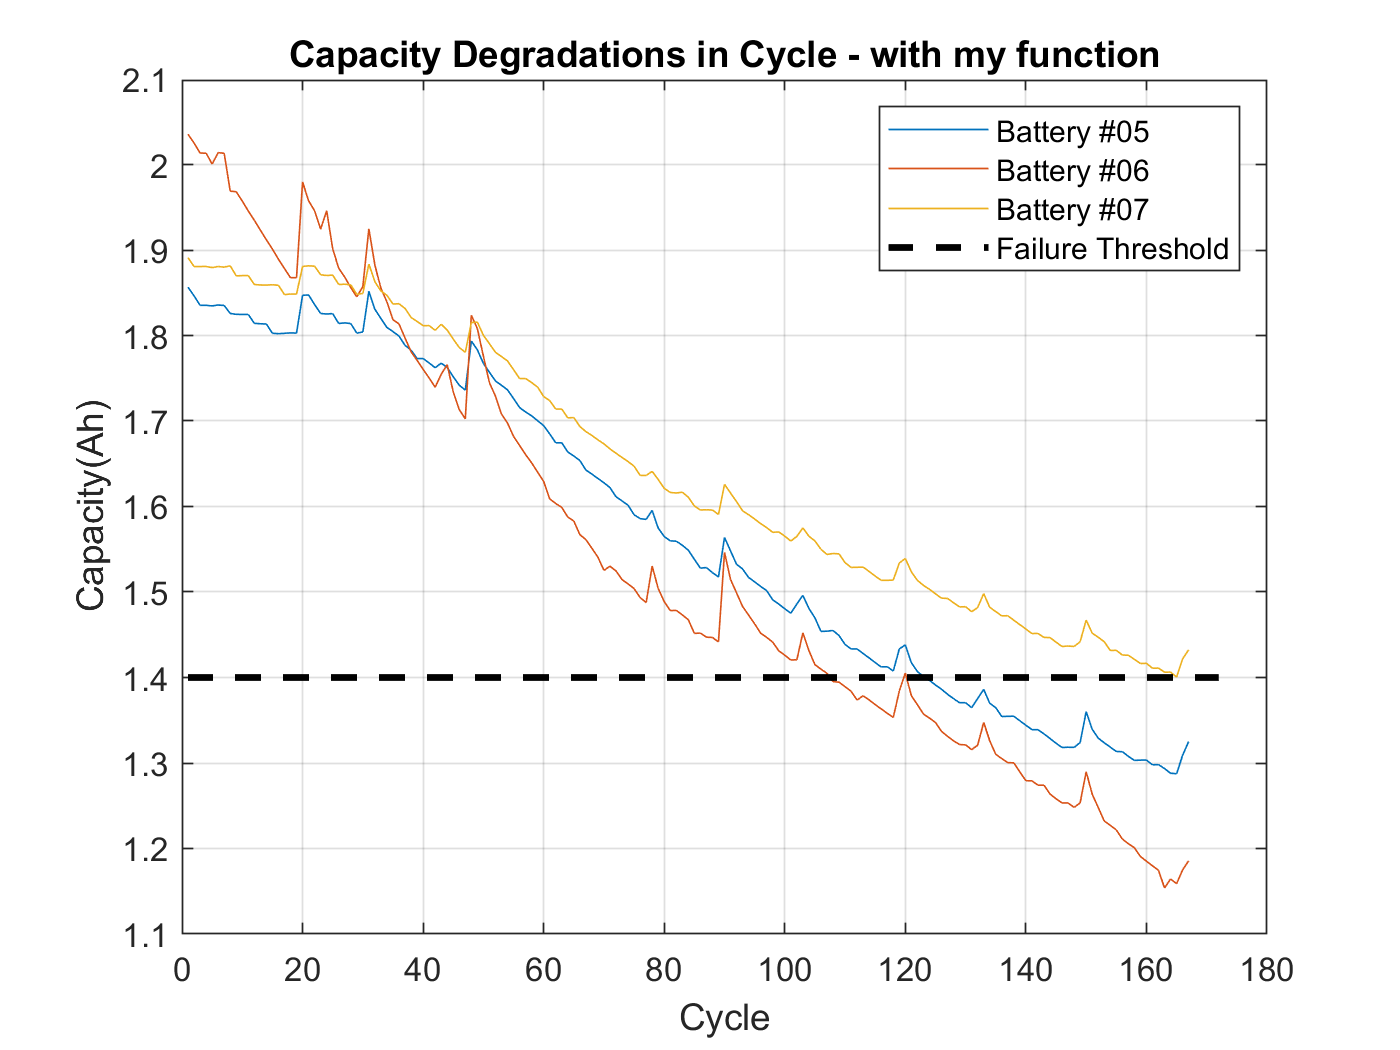

plot(cap_gen_05), hold on, plot(cap_gen_06), plot(cap_gen_07)
plot(1:len, 1.4*ones(1, len),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #05', 'Battery #06', 'Battery #07', 'Failure Threshold')
title('Capacity Degradations in Cycle - with my function')

load cap_05             
load cap_06             
load cap_07             
load cap_0506           
load cap_0605           
load cap_05plus06       
load cap_05plus07       
load cap_06plus07       
load cap_05plus06plus07 

len = length(cap_05) + 5

len = 97

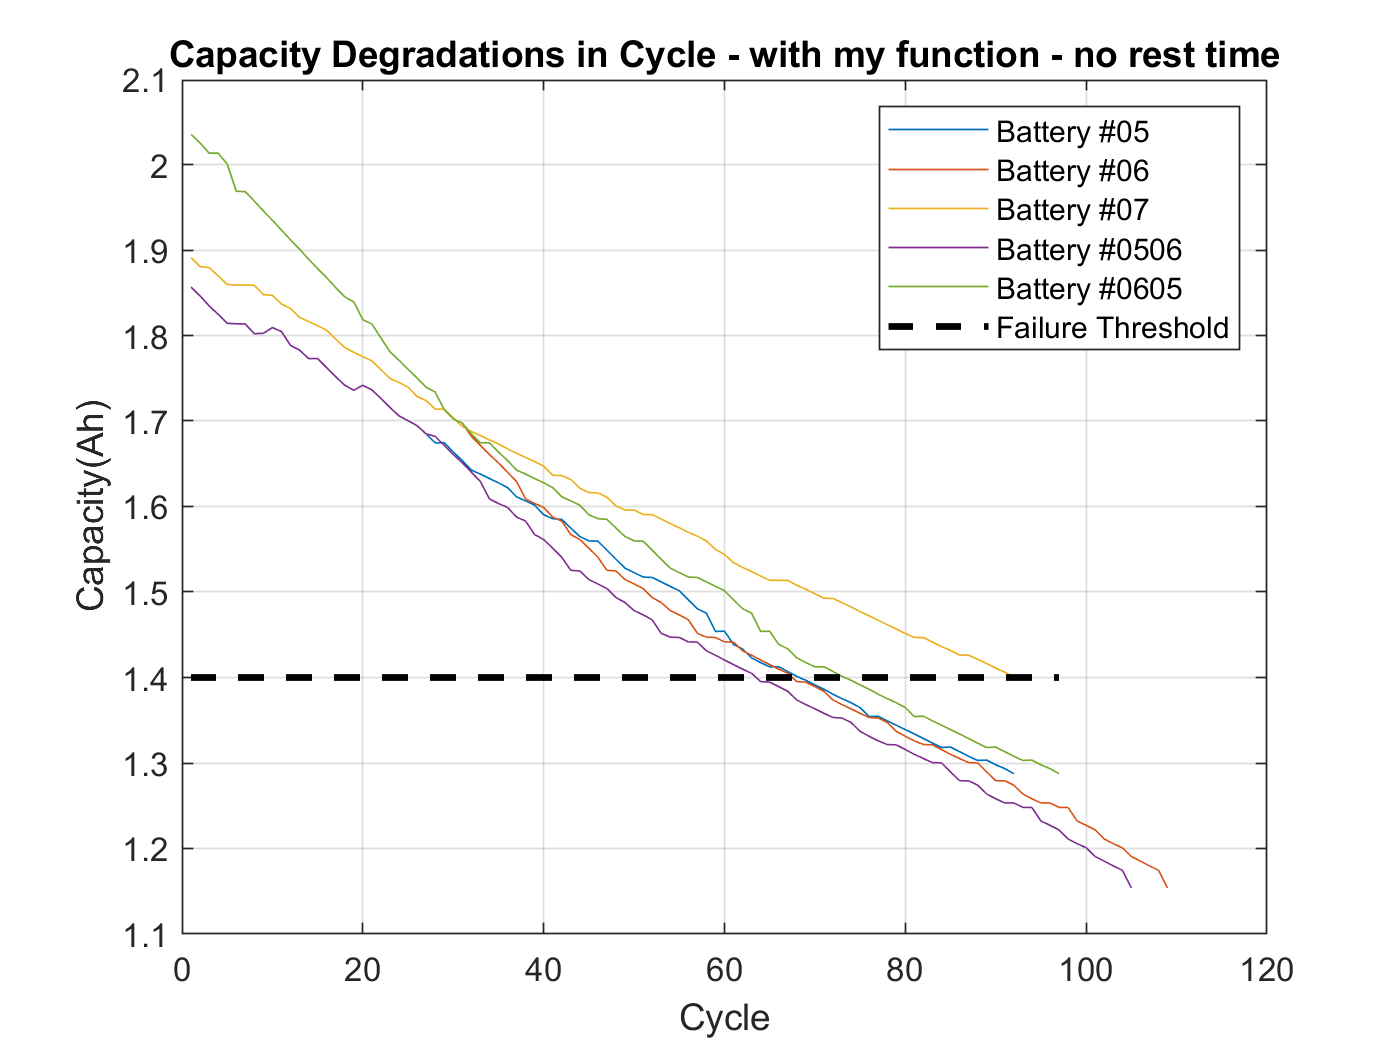

plot(cap_05), hold on, plot(cap_06), plot(cap_07), plot(cap_0506), plot(cap_0605)
plot(1:len, 1.4*ones(1, len),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #05', 'Battery #06', 'Battery #07', 'Battery #0506','Battery #0605','Failure Threshold')
title('Capacity Degradations in Cycle - with my function - no rest time')

len = length(cap_05plus06plus07) + 5

len = 298

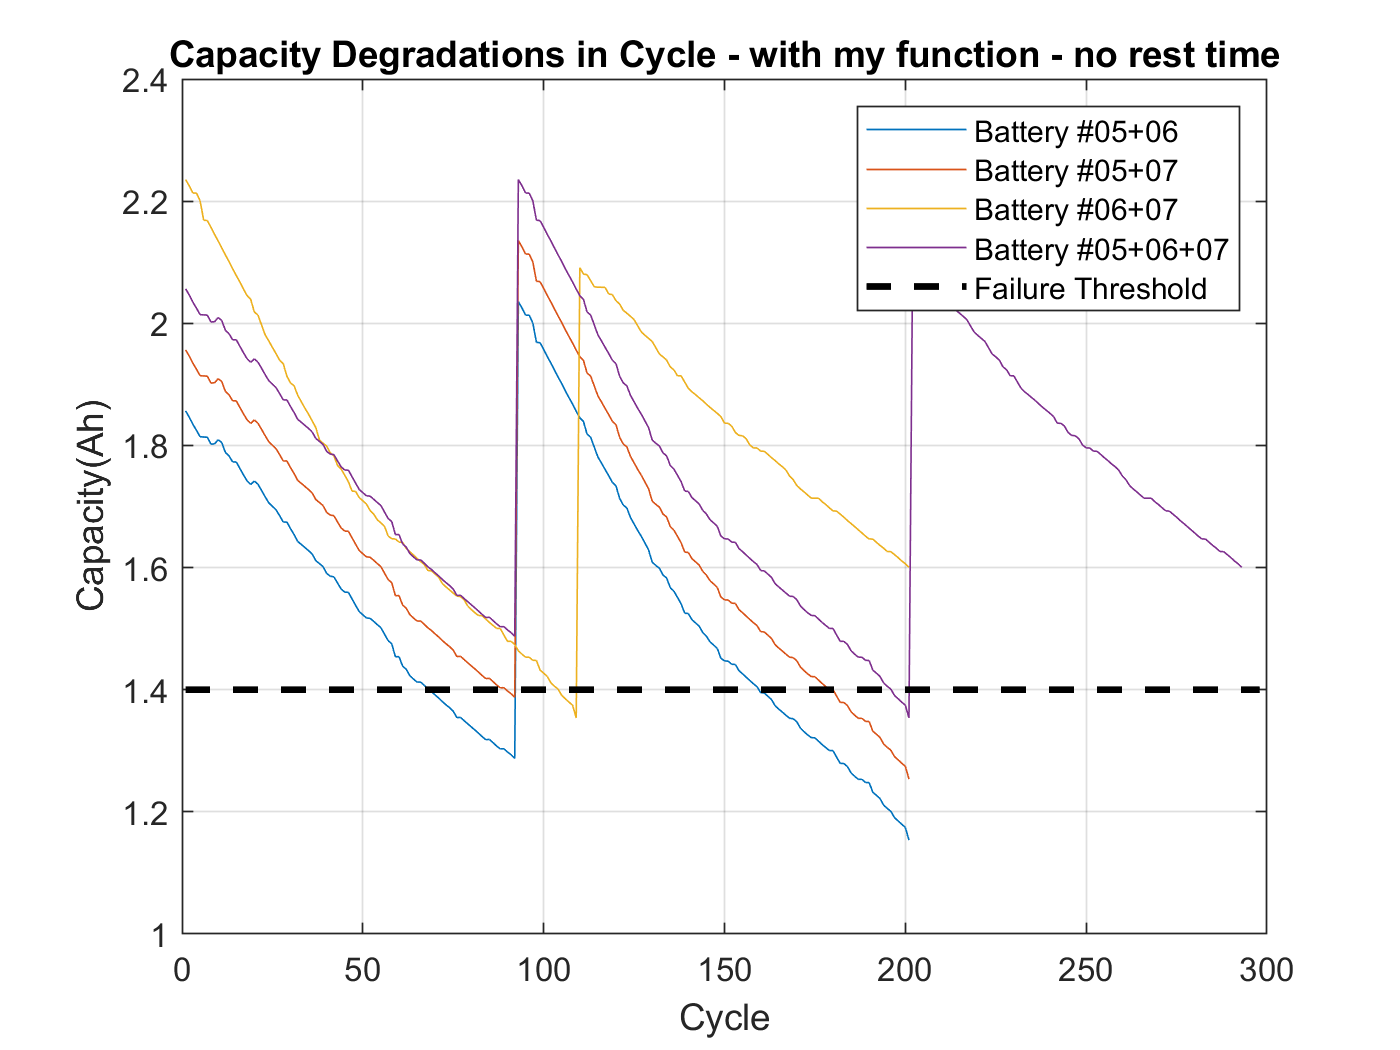

% add 0.1 to show graph more easily
plot(cap_05plus06), hold on, plot(cap_05plus07+0.1), plot(cap_06plus07+0.2), plot(cap_05plus06plus07+0.2)
plot(1:len, 1.4*ones(1, len),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #05+06', 'Battery #05+07', 'Battery #06+07', 'Battery #05+06+07','Failure Threshold')
title('Capacity Degradations in Cycle - with my function - no rest time')